%% 3.
clear variables;

R1 = 2.2e3;
R2 = 4.7e3;
R3 = 1e3;
R4 = 1e3;
C1 = 0.1e-6;

k1 = R2 / R1 * R4/R3;
T1 = R2 * C1;

num = [R2 / R1];
den = [R2 * C1 1];
H1 = tf(num,den)

H1 =
 
      2.136
  -------------
  0.00047 s + 1
 
Continuous-time transfer function.




R23 = 2.2e3;

k2 = R23 / R1 * R4/R3;
T2 = R23 * C1;

num = [R23 / R1];
den = [R23 * C1 1];
H2 = tf(num,den)

H2 =
 
        1
  -------------
  0.00022 s + 1
 
Continuous-time transfer function.




figure,
step(H1);hold;

Current plot held


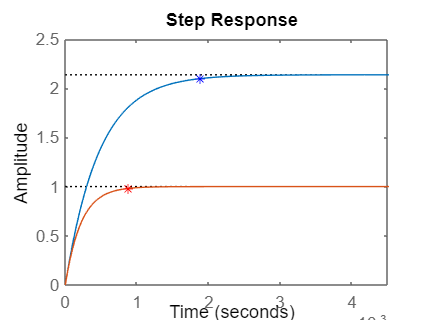

plot(4*T1,0.98*k1, "*b"); xlabel('Time'); ylabel('Amplitude'); grid;
step(H2);
plot(4*T2,0.98*k2, "*r"); xlabel('Time'); ylabel('Amplitude'); grid;